# Frequency Response Function Estimate

clear; clc; clear all; %clear all variables from the workspace
%frfest.m
%Birdsong June 2024
%Read experimental data file and overlay estimated TF frequency response plots


## load data

load 'bodedata.mat' %loads the experimental frequency response data file
load ControlSystemDesignerSession.mat %loads RL tool data from PID

## parameters

format shortG
wp1 = 2.5;
wp2 = 4.5;

mp1 = 10;
mp2 = 1.778;

zeta1 = .06;
zeta2 = .14;

wn1 = wp1/sqrt(1-2*zeta1^2)

wn1 =         2.509


wn2 = wp2/sqrt(1-2*zeta2^2)

wn2 =        4.5909


## 4th order CE

% first 2nd Order CE
CE1 = [1, 2*zeta1*wn1, wn1^2]

CE1 =             1      0.30109       6.2953


% second 2nd Order CE
CE2 = [1, 2*zeta2*wn2, wn2^2]

CE2 =             1       1.2854       21.076


% combined 
num = [10*(wn1^2)*(wn2^2)] %define the numerator

num =        1326.8


den = conv(CE2, CE1) %define the denominator 

den =             1       1.5865       27.759       14.438       132.68


## define your estimated open-loop tranfer function here using the TF command

gp=tf(num,den)

gp =
 
                      1327
  ---------------------------------------------
  s^4 + 1.587 s^3 + 27.76 s^2 + 14.44 s + 132.7
 
Continuous-time transfer function.
Model Properties


P = pole(gp)

P =      -0.64272 +     4.5457i
     -0.64272 -     4.5457i
     -0.15054 +     2.5045i
     -0.15054 -     2.5045i


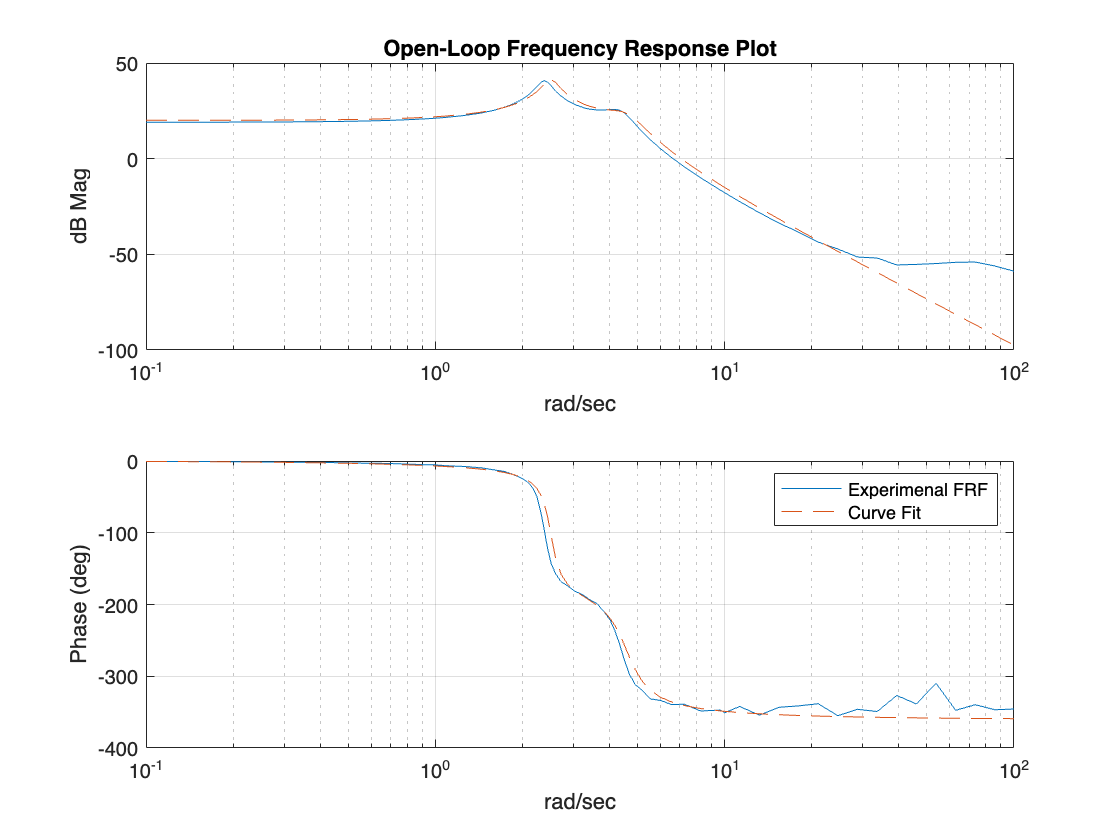

figure()
[mmod2,pmod2]=bode(gp,wout);%compute freq resp with w (rad/s) 

%plot the bode diagram
figure(1);subplot(211)
semilogx(wout,20*log10(magdata),wout,20*log10(squeeze(mmod2)),'--');
grid;xlabel('rad/sec');ylabel('dB Mag');
title('Open-Loop Frequency Response Plot');
subplot(212);
semilogx(wout,phasedata,wout,squeeze(pmod2),'--'); 
xlabel('rad/sec');ylabel('Phase (deg)');grid
legend('Experimenal FRF','Curve Fit')

[A B C D] = tf2ss(num,den);

stepinfo(gp)

ans = struct with fields:
         RiseTime: 0.37995
    TransientTime: 26.479
     SettlingTime: 27.836
      SettlingMin: 0.47525
      SettlingMax: 23.112
        Overshoot: 131.12
       Undershoot: 0
             Peak: 23.112
         PeakTime: 1.3686


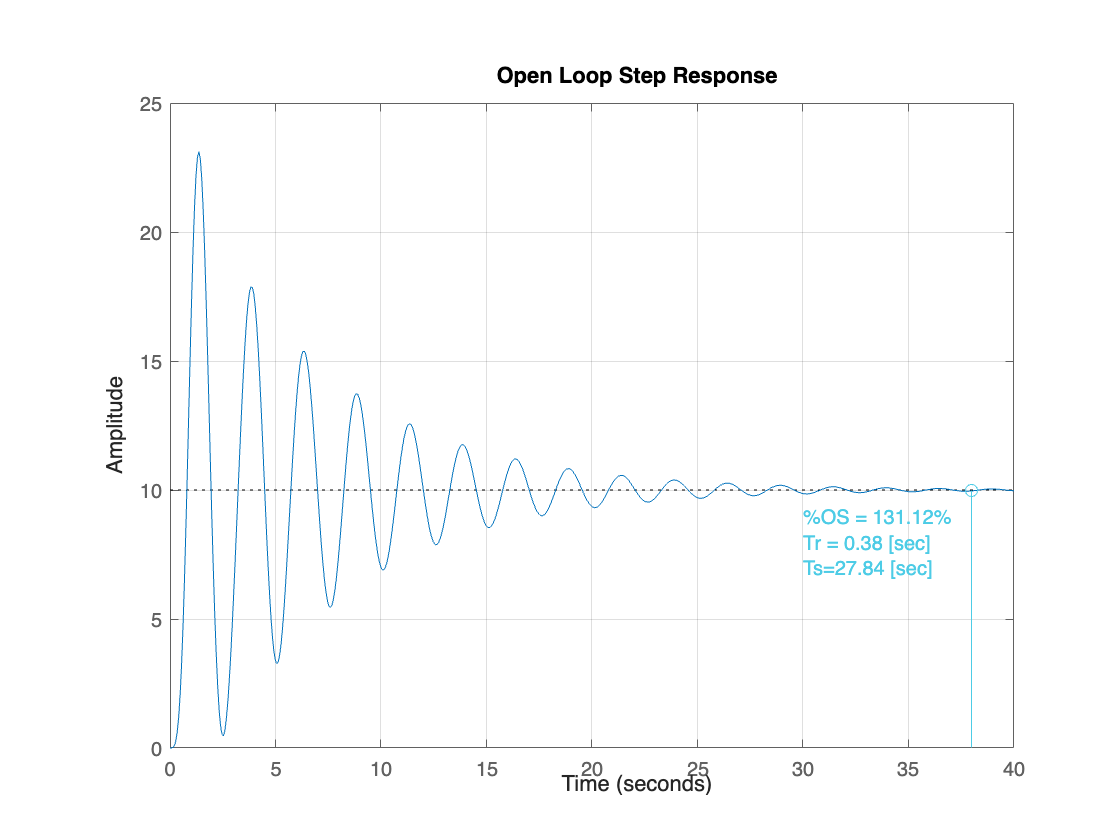


% Open Loop Step Response
figure()
step(gp)
title('Open Loop Step Response')
grid on
text(30,9,'%OS = 131.12%','color', [0.3 0.8 0.9])
text(30,8,'Tr = 0.38 [sec]','color', [0.3 0.8 0.9])
text(30,7,'Ts=27.84 [sec]','color', [0.3 0.8 0.9])
hold on
stem(38,10,'color', [0.3 0.8 0.9])
hold off

% RL tool

%rltool(gp)
session = ControlSystemDesignerSession;
plotData = session.PlotsManager.ResponsePlots.PlotData.Options

plotData =

                   Normalize: 'off'
         SettleTimeThreshold: 0.02
              RiseTimeLimits: [0.1 0.9]
                   TimeUnits: 'seconds'
    ConfidenceRegionNumberSD: 1
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.15 0.15 0.15]
                        XLim: {[0 40]}
                        YLim: {[0 0.00035]}
                    XLimMode: {'manual'}
                    YLimMode: {'manual'}



%full state feedback controller

% Ts = 0.2;
% wn3 = 2.5;
% zeta3 = 20/wn3;
% wn4 = 4.5;
% zeta4 = 20/wn4;
% 
% wd3 = wn3*sqrt(1-zeta3^2)
% wd4 = wn4*sqrt(1-zeta4^2)
%new_poles = [-20+wd3, -20-wd3, -20+wd4, -20-wd4];

stepinfo(clsys)

ans = struct with fields:
         RiseTime: 0.77219
    TransientTime: 1.3259
     SettlingTime: 1.3259
      SettlingMin: 0.78312
      SettlingMax: 0.87439
        Overshoot: 0.67904
       Undershoot: 0
             Peak: 0.87439
         PeakTime: 1.796


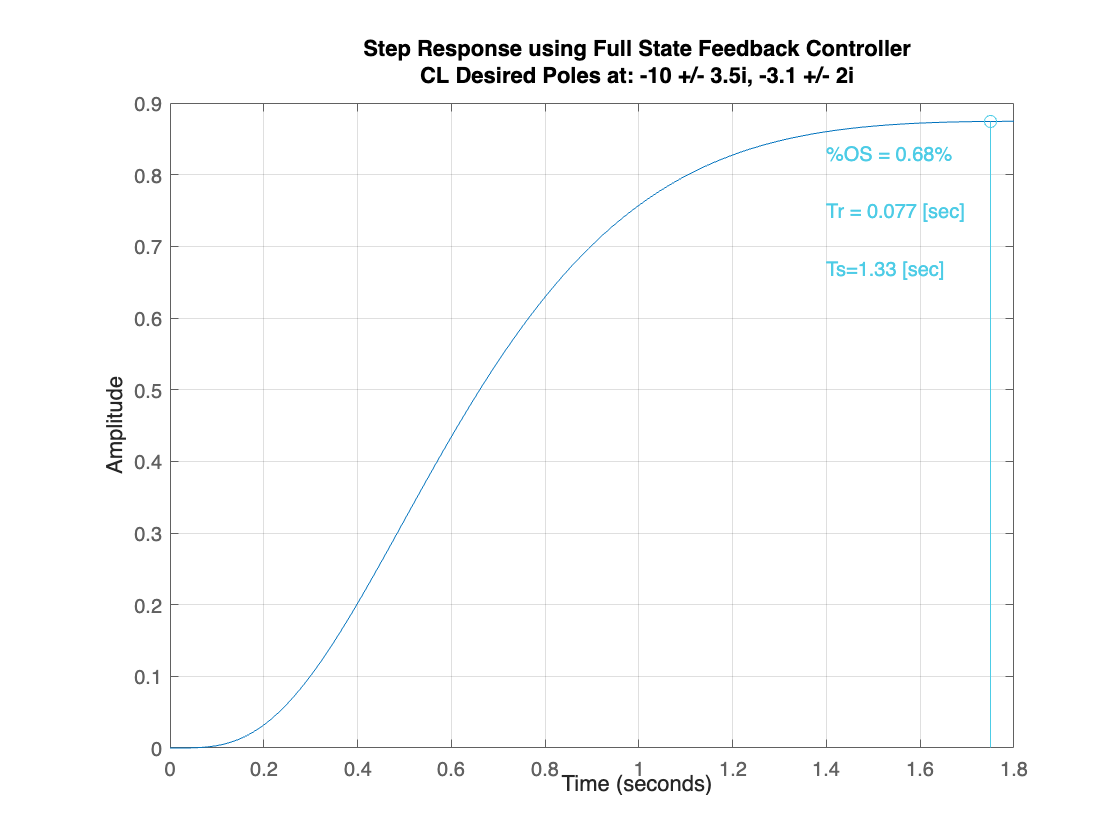


new_poles = [-10+3.5i,-10-3.5i, -3.1+2i, -3.1-2i];
K = place(A,B,new_poles) ;
a_cl = A-B*K;
clsys = ss(a_cl,B,C,D) ;
step(clsys)
title({'Step Response using Full State Feedback Controller','CL Desired Poles at: -10 +/- 3.5i, -3.1 +/- 2i'})
grid on
text(1.4,0.83,'%OS = 0.68%','color', [0.3 0.8 0.9])
text(1.4,0.75,'Tr = 0.077 [sec]','color', [0.3 0.8 0.9])
text(1.4,0.67,'Ts=1.33 [sec]','color', [0.3 0.8 0.9])
hold on
stem(1.75,0.874,'color', [0.3 0.8 0.9])
hold off

%LQR
w = 1;
Q = [w 0 0 0;
     0 w*50 0 0;
     0 0 w 0;
     0 0 0 w*5000];
R = 0.003; 
%R = 1;
[Klqr, S, P]= lqr(A, B, Q, R);
sys1 = ss(A-B*Klqr,B,C,D);
sys1;

stepinfo(sys1)

ans = struct with fields:
         RiseTime: 0.71539
    TransientTime: 2.1168
     SettlingTime: 2.1168
      SettlingMin: 0.92175
      SettlingMax: 1.0757
        Overshoot: 5.2183
       Undershoot: 0
             Peak: 1.0757
         PeakTime: 1.5762


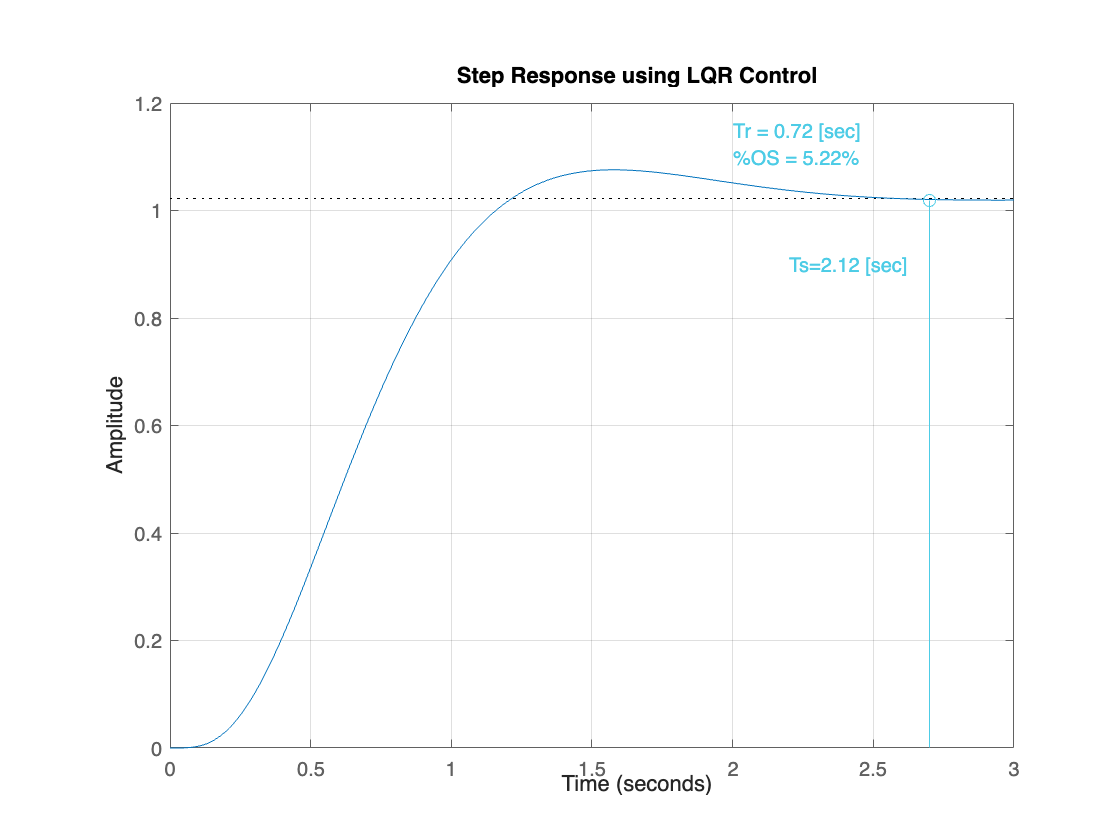


figure()
step(sys1)
title({'Step Response using LQR Control'})
grid on
text(2,1.1,'%OS = 5.22%','color', [0.3 0.8 0.9])
text(2,1.15,'Tr = 0.72 [sec]','color', [0.3 0.8 0.9])
text(2.2,0.9,'Ts=2.12 [sec]','color', [0.3 0.8 0.9])
hold on
stem(2.7,1.019,'color', [0.3 0.8 0.9])
hold off